# Create a Report That Has a List of Captions Section

This example shows how to create a list of captions section in a report. The example generates a report about physics equations and adds a list of the captions of the equations to the report. 

Import the DOM and Report API packages so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*
import mlreportgen.report.*

Create a report.

rpt = Report("physics","docx");

Add a title page and a table of contents to the report.

tp = TitlePage();
tp.Title = "Physics Principles";
tp.Author = "John Doe";
append(rpt,TableOfContents);

Create a list of captions section.

loc = ListOfCaptions();
loc.Title = "List of Equations";

Define an automatic numbering stream name to use with the `ListOFCaptions` object.

equationStreamName = "equation";
loc.AutoNumberStreamName = equationStreamName;

Add the list of captions section to the report.

append(rpt,loc);

Create chapters for the report content. For this example, create two chapters. Each chapter has one equation.

Create the first chapter. Add a paragraph and add an equation to it.

ch1 = Chapter("Force");
append(ch1,Paragraph("Calculate force by multiplying mass and acceleration."));
eq1 = Equation("F = ma");
append(ch1,eq1);

Create a paragraph for the equation caption and associate the automatic numbering stream name with the caption.

caption1 = Paragraph("Equation ");
append(caption1,AutoNumber(equationStreamName));

Define a style for the captions. Include an `mlreportgen.report.CounterInc` object to increment the counter for the numbering stream.

equationCaptionsStyle = {HAlign("center"),CounterInc(equationStreamName),WhiteSpace("preserve")};
caption1.Style = equationCaptionsStyle;

Add the rest of the caption text and add the caption to the chapter.

append(caption1,".");
append(caption1," Force");
append(ch1,caption1);

Add the chapter to the report.

append(rpt,ch1);

Create the second chapter. Add a paragraph and add an equation to the paragraph.

ch2 = Chapter("Momentum");
append(ch2,Paragraph("Calculate momentum by multiplying mass and velocity."));
eq2 = Equation("p = mv");
append(ch2,eq2);

Create a paragraph for the equation caption and associate the automatic numbering stream name with the caption.

caption2 = Paragraph("Equation ");
append(caption2,AutoNumber(equationStreamName));

Specify the style for the caption.

caption2.Style = equationCaptionsStyle;

Add the rest of the caption text and add the caption to the chapter. 

append(caption2,".");
append(caption2," Momentum");
append(ch2,caption2);

Add the chapter to the report.

append(rpt,ch2);

Close and view the report.

close(rpt);
rptview(rpt);

Here is the list of equations in the report:

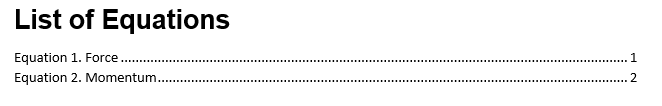

*Copyright 2020 The MathWorks, Inc.*